# Visual degrees and retinal mm

It is sometimes necessary to convert measurements made along the retina from one set of units (degrees of visual angle) to another (millimeters). This value is also sometimes called the retinal magnification factor (RMF). While there are rules-of-thumb for this conversion (e.g., 0.3 mm / degree), the precise value is complicated to obtain. This is because of individual varation in the ellipsoidal dimensions of the retina, as well as in the optics and accommodative state of the eye.

This demo explores the concepts and details related to this conversion.

## A basic calculation of the RMF

Keeping things simple, we can define a default model eye, and measure the unit conversion for the vertex point on the longitudinal axis of the retina:

wavelength = 555;
sphericalAmetropia = 0;
eye = modelEyeParameters('spectralDomain',wavelength,'sphericalAmetropia',sphericalAmetropia);
calcMmRetinaPerDeg(eye)

ans = 0.2815

## RMF at the fovea

To be a bit more precise, we can define visual angle with respect to the approximate incident nodal point of the eye, and the field location as corresponding to the fovea:

fieldAngularPosition = eye.landmarks.fovea.degField;
rayOriginDistance = 1e4;
angleReferenceCoord = eye.landmarks.incidentNode.coords;
distanceReferenceCoord = calcPrincipalPoint(eye);

We also need to decide the direction for which we would like to measure the conversion. For example, we might measure the distance between two points on the retina that are separated by one degree of horizontal field angle:

deltaAngles = [1 0];

We now call the function with these optional inputs:

mmPerDeg = calcMmRetinaPerDeg(eye,fieldAngularPosition,deltaAngles,rayOriginDistance,angleReferenceCoord,distanceReferenceCoord)

mmPerDeg = 0.2811

As can be seen, there is a small difference in the unit relationship depending upon the position in the visual field that we choose to interogate.

## RMF as a function of field position

We can repeat the calculation, now for positions along the horizontal meridian, relative to the fovea, and plot the resulting function:

hPos = 1:1:50;  % The range of visual field eccentricities
for ii = 1:length(hPos)
    thisLocation = fieldAngularPosition+[hPos(ii) 0];
    mmPerDeg(ii) = calcMmRetinaPerDeg(eye,thisLocation,deltaAngles,rayOriginDistance,angleReferenceCoord,distanceReferenceCoord);
end
figure
plot(hPos,mmPerDeg,'-k')
ylabel('mm/deg');
xlabel('horizontal field location relative to fovea [deg]');
xlim([0 50])

## Comparison to Drasdo & Fowler

One of the "species" of model eye available in the software is Drasdo & Fowler 1974. We can examine the behavior of this model eye.

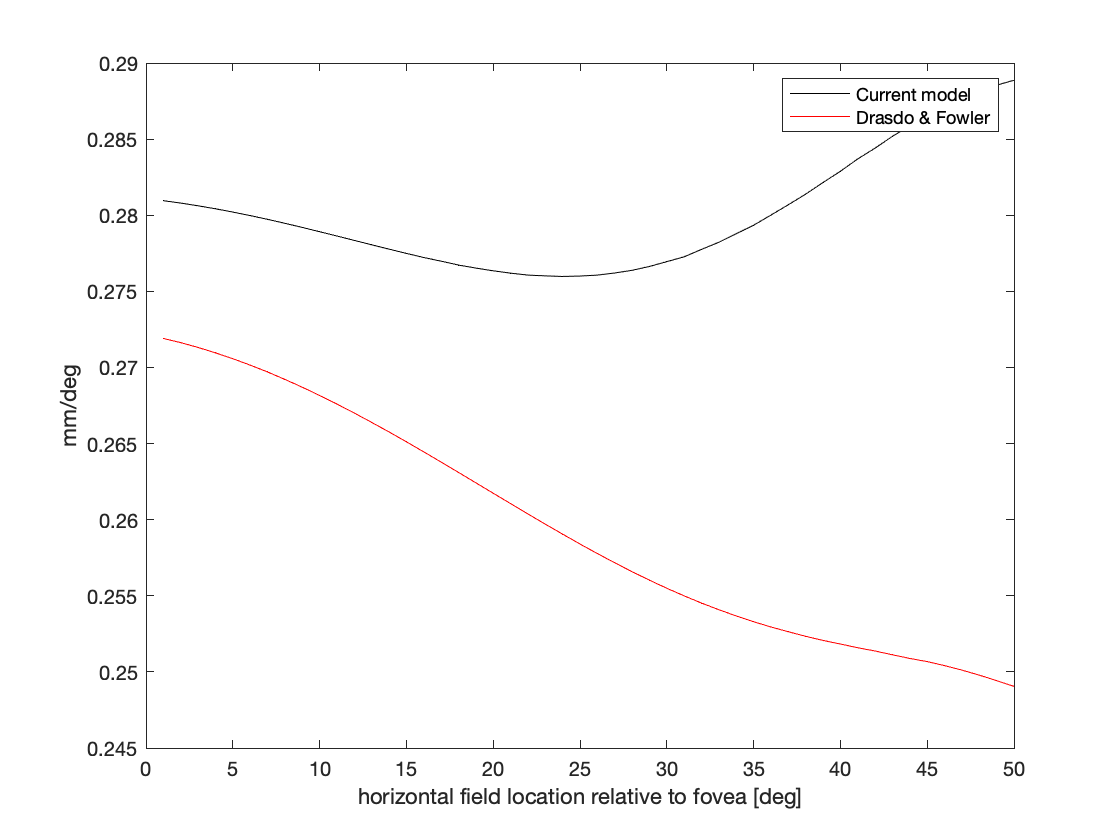

eyeDrasdo = modelEyeParameters('species','Drasdo');
fieldAngularPosition = eyeDrasdo.landmarks.fovea.degField;
angleReferenceCoord = eyeDrasdo.landmarks.incidentNode.coords;
distanceReferenceCoord = calcPrincipalPoint(eyeDrasdo);
mmPerDeg = [];
for ii = 1:length(hPos)
    thisLocation = [hPos(ii)+fieldAngularPosition(1), fieldAngularPosition(2)];
    mmPerDeg(ii) = calcMmRetinaPerDeg(eyeDrasdo,thisLocation,deltaAngles,rayOriginDistance,angleReferenceCoord,distanceReferenceCoord);
end
hold on
plot(hPos,mmPerDeg,'-r');
legend({'Current model','Drasdo & Fowler'});

There is a notable difference in the form of these functions at greater eccentricies, owing to the spherical form of the retina in the Drasdo model.

## RMF as a function of polar angle

The vitreous chamber of the eye has an ellipsoidal form. As a consequence, the RMF will vary depending upon if the measurement is made along the horizontal or vertical meridian.

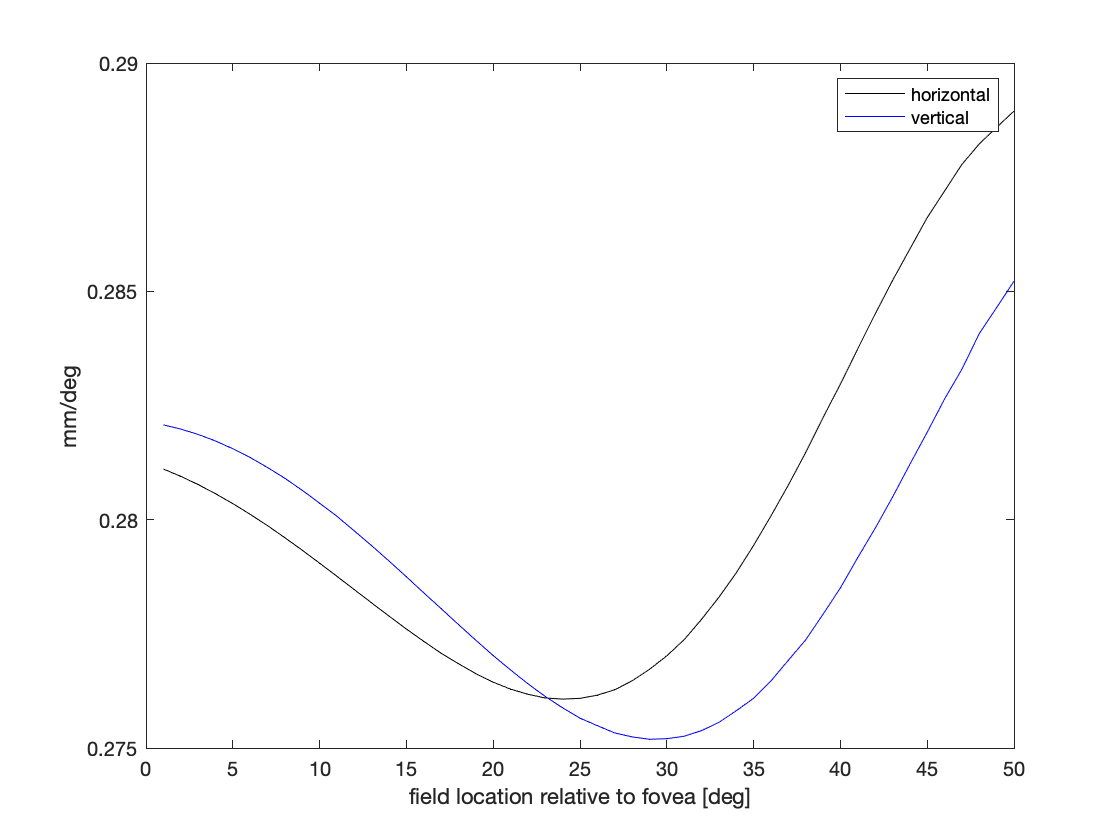

hvPos = 1:1:50;  % The range of visual field eccentricities
for ii = 1:length(hvPos)
    thisLocation = fieldAngularPosition+[hvPos(ii) 0];
    deltaAngles = [1 0];
    mmPerDeg_horiz(ii) = calcMmRetinaPerDeg(eye,thisLocation,deltaAngles,rayOriginDistance,angleReferenceCoord,distanceReferenceCoord);
    thisLocation = fieldAngularPosition+[0 hvPos(ii)];
    deltaAngles = [0 1];
    mmPerDeg_vert(ii) = calcMmRetinaPerDeg(eye,thisLocation,deltaAngles,rayOriginDistance,angleReferenceCoord,distanceReferenceCoord);
end
figure
plot(hvPos,mmPerDeg_horiz,'-k')
hold on
plot(hvPos,mmPerDeg_vert,'-b')
ylabel('mm/deg');
xlabel('field location relative to fovea [deg]');
legend([{'horizontal','vertical'}])
xlim([0 50])

## RMF as a function of spherical refractive error

The size and shape of the vitreous chamber, and the axial length of the eye, changes systematically with spherical refractive error. These factors have a substantial effect upon the calculated RMF.

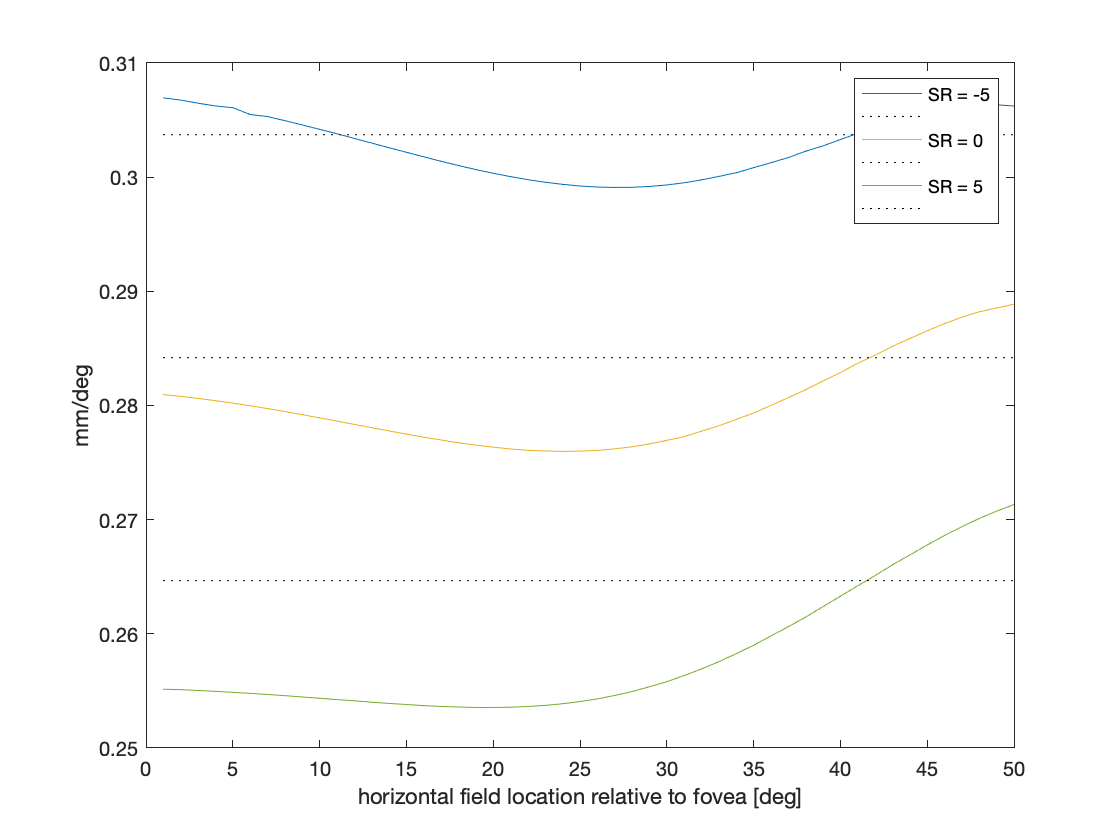

hPos = 1:1:50;  % The range of visual field eccentricities
SRs = [-5 0 5];
deltaAngles = [1 0];
figure
legendText = {};
for ss = 1:length(SRs)
    eye = modelEyeParameters('spectralDomain',wavelength,'sphericalAmetropia',SRs(ss));
    fieldAngularPosition = eye.landmarks.fovea.degField;
    rayOriginDistance = 1e4;
    angleReferenceCoord = eye.landmarks.incidentNode.coords;
    distanceReferenceCoord = calcPrincipalPoint(eye);
    for ii = 1:length(hPos)
        thisLocation = fieldAngularPosition+[hPos(ii) 0];
        mmPerDeg(ii) = calcMmRetinaPerDeg(eye,thisLocation,deltaAngles,rayOriginDistance,angleReferenceCoord,distanceReferenceCoord);
    end
    plot(hPos,mmPerDeg,'-')
    hold on
    % Add the Bennet formula
    q =0.01306 *(eye.meta.axialLength-1.82);
    plot([min(hPos) max(hPos)],[q q],':k')
    % Assemble the legend text
    legendText{end+1} = sprintf('SR = %d',SRs(ss));
    legendText{end+1} = '';
end
ylabel('mm/deg');
xlabel('horizontal field location relative to fovea [deg]');
legend(legendText)
xlim([0 50])

The RMF varies systematically as a function of spherical refractive error, and further as a function of horizontal eccentricitty. The dashed lines indicate the values for the RMF provided by Bennett 1993 solution:

- Bennett, Arthur G., Alicja R. Rudnicka, and David F. Edgar. "Improvements on Littmann's method of determining the size of retinal features by fundus photography." *Graefe's Archive for Clinical and Experimental Ophthalmology* 232.6 (1994): 361-367.

which takes the form:

`RMF (mm / deg) = 0.01306 x (AL – 1.82)`

where AL is the axial length of the eye in mm.

The Bennett solution is in good general agreement current model. The RMF specified by the Bennett equation, however, is constant as a function of eccentricity and polar angle, and varies as a linear function of axial length. 